% Reaction Wheel Attitude Control Simulation
% -----------------------------------------
% Simulates a PD-controlled reaction wheel system for satellite attitude
% regulation (Hubble-inspired parameters).
%
% Author: Bilal Ahmad
% Date: Jan 2026
% 
% State variables:
%   th  - satellite attitude (rad)
%   w   - satellite angular velocity (rad/s)
%   ww  - wheel angular velocity (rad/s)


% Parameters are order-of-magnitude estimates inspired by Hubble-class spacecraft and are chosen for numerical stability and illustrative control behavior.

wwi = input("enter the wheel's current angular speed: ")

wwi = 3

thi = input("enter current attitude wrt sun: ")

thi = 1

thref = input ("enter target attitude: ")

thref = 10

wi = 0;
tol_rate = 0.01;
tol = 1e-4;
th = thi;
w = wi;
ww = wwi;
err = th - thref;
Is = 77000; %MOI of satellite
Iw = 8; %MOI of wheels
Tw = 0;
Td = 1e-6; %disturbing torque
Kp = 1e-3; %proportinality constant
Kd = 1e-2; %derivative constant
time = linspace(0, 30000, 240000);
step = 0.125;
n=1;
Nm = length(time);
wwv=zeros(1,Nm);
wv=zeros(1,Nm);
Twv=zeros(1,Nm);
thv=zeros(1,Nm);
wwv(1) = ww;
wv(1) = w;
Twv(1) = Tw;
thv(1) = th;
while ( (abs(err) > tol) || (abs(w) > tol_rate) ) && n < Nm
    n = n+1;
    Tw = -Kp*err - Kd*w;
    Tmax = 0.5;               
    Tw = max(-Tmax, min(Tmax, Tw));
    wdot = (Tw+Td)/Is;
    wwdot = (-Tw)/Iw;
    ww = ww + wwdot*step;
    w = w + wdot*step;
    delth = w*step;
    th = th + delth;
    err = th - thref;
    wwv(n) = ww;
    wv(n) = w;
    Twv(n) = Tw;
    thv(n) = th;
end
plott = time(1:n)

plott = 1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006


Hv = Is*wv(1:n)+Iw*wwv(1:n)

Hv =    24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000   24.0000


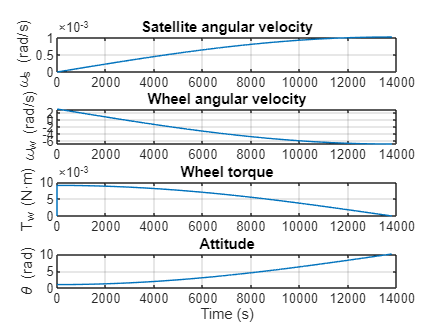

figure

subplot(4,1,1)
plot(plott, wv(1:n))
title('Satellite angular velocity')
ylabel('\omega_s (rad/s)')
grid on

subplot(4,1,2)
plot(plott, wwv(1:n))
title('Wheel angular velocity')
ylabel('\omega_w (rad/s)')
grid on

subplot(4,1,3)
plot(plott, Twv(1:n))
title('Wheel torque')
ylabel('T_w (N·m)')
grid on

subplot(4,1,4)
plot(plott, thv(1:n))
title('Attitude')
xlabel('Time (s)')
ylabel('\theta (rad)')
grid on

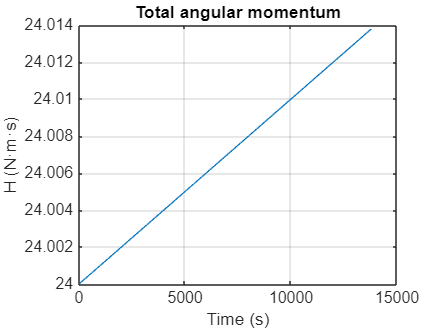


figure
plot(plott, Hv)
title('Total angular momentum')
xlabel('Time (s)')
ylabel('H (N·m·s)')
grid on